
clear;

csvFolderName = "StockVibro";
clockTimeLimit = 3; % 体験時間 (s)
stopTime = clockTimeLimit;
stopTable = table(stopTime);
writetable(stopTable, csvFolderName + '\' + "stop.csv");

Stock Left

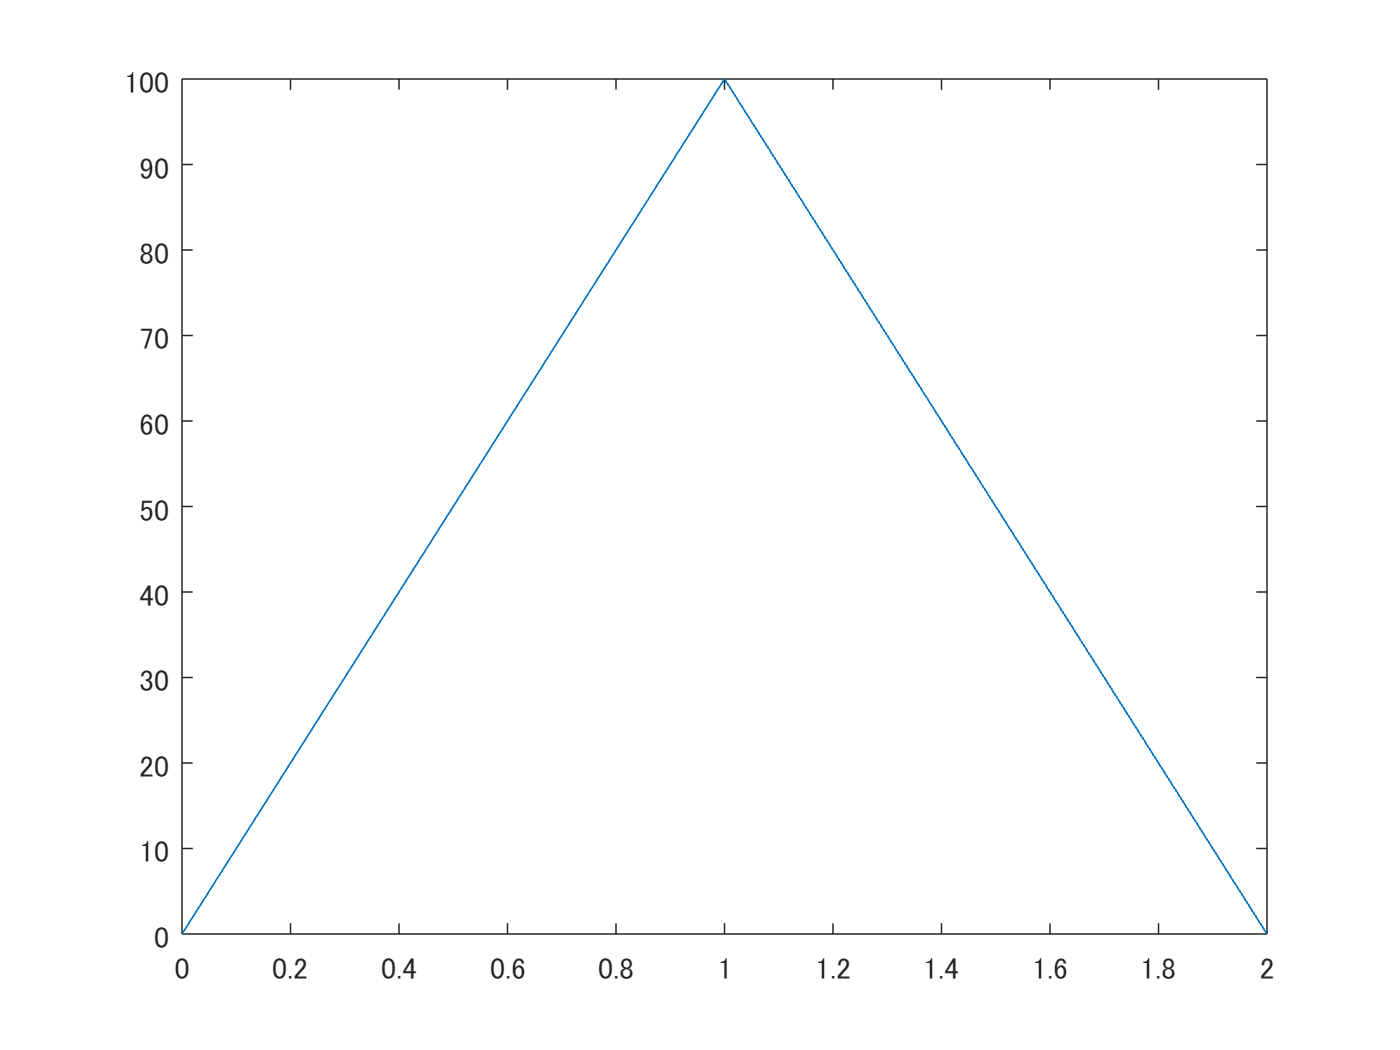

dt = 0.05;
T = 1;
xLimit = 100; % 単位 (mm)
clockTime = (0:dt:2*T)';

x = [
    xLimit * (0:dt:T-dt)'/T;
    -xLimit * ((T:dt:2*T)' - T)/T + xLimit;
    ];
figure;
plot(clockTime, x);

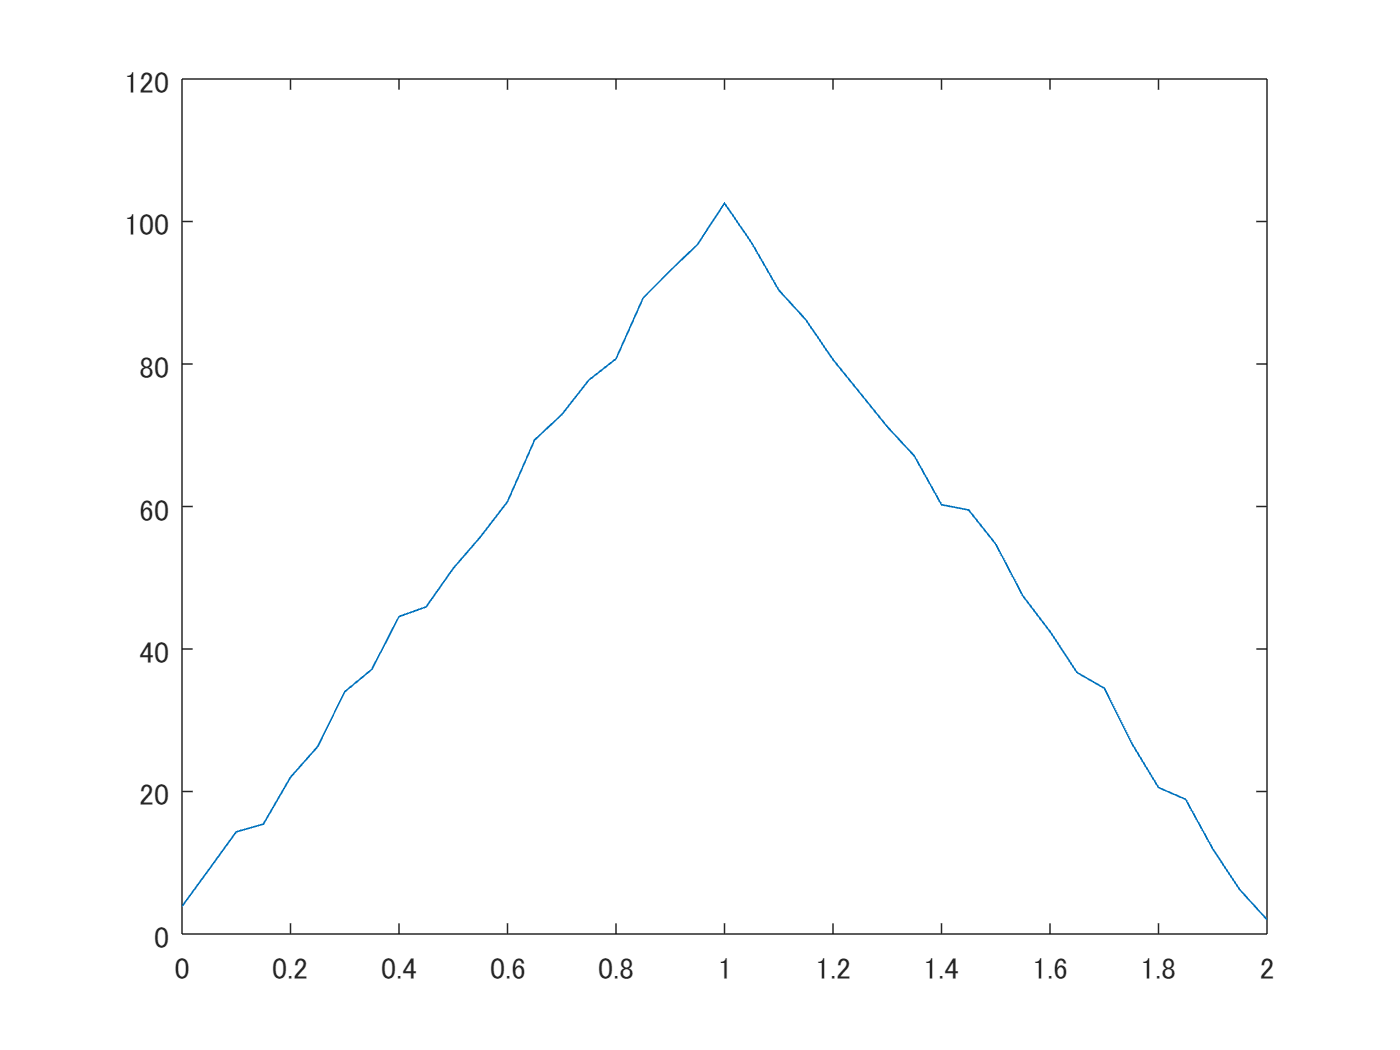

F = 9; % 振動周波数 Hz
Amp = 5; % 振動振幅 mm
% x = x + Amp*sin(F*2*pi*clockTime);
x = x + Amp*rand(size(clockTime));

figure;
plot(clockTime, x);

StockVibroCSV = table(clockTime, x)

StockVibroCSV = 41×2 table
    clockTime      x   
    _________    ______

         0       3.8746
      0.05       9.0865
       0.1       14.343
      0.15       15.422
       0.2       21.999
      0.25       26.299
       0.3           34
      0.35       37.157
       0.4       44.553
      0.45       45.909
       0.5       51.319
      0.55       55.728
       0.6        60.68
      0.65       69.346
       0.7       72.899
      0.75       77.749


writetable(StockVibroCSV, csvFolderName + '\' + "StockVibro.csv");

function showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
    t = 0:0.001:deltaTime(1);
    x = absolutePosition(1)*(1 + cos(pi*t/deltaTime(1) + pi))/2;
    plot(t + clockTime(1), x);
    hold on;
    for idx = 2:length(clockTime)
        t = 0:0.01:deltaTime(idx);
        x = (absolutePosition(idx) - absolutePosition(idx-1)) * (1 + cos(pi*t/deltaTime(idx) + pi))/2 + absolutePosition(idx - 1);
        plot(t + clockTime(idx), x);
    end
end

function [ret_x, ret_t] = showGraph(clockTime, deltaTime, absolutePosition)
    % ret_t = [];
    t = (0:0.001:deltaTime(1))';
    x = absolutePosition(1)*(1 + cos(pi*t/deltaTime(1) + pi))/2;
    % plot(t + clockTime(1), x);
    ret_x = x;
    ret_t = t + clockTime(1);
    hold on;
    for idx = 2:length(clockTime)
        t = (0:0.01:deltaTime(idx))';
        x = (absolutePosition(idx) - absolutePosition(idx-1)) * (1 + cos(pi*t/deltaTime(idx) + pi))/2 + absolutePosition(idx - 1);
        % plot(t + clockTime(idx), x);
        ret_t = [ret_t; t + clockTime(idx)];
        ret_x = [ret_x; x];
    end
    plot(ret_t, ret_x);
end